clearvars; close('all')


months={'07','08','09','10','11'};
titles={'July','August','September','October','November'};
for ii=1:numel(months)
    fname=['SCAT_data_qc_' char(months(ii)) '.mat'];
    load(fname)
    

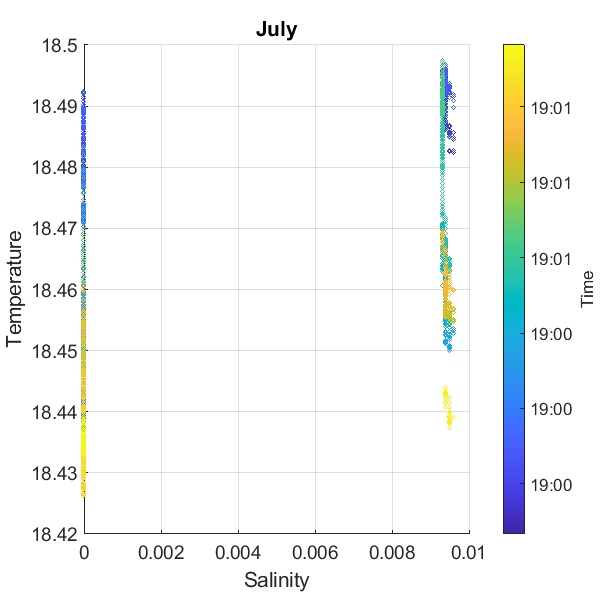

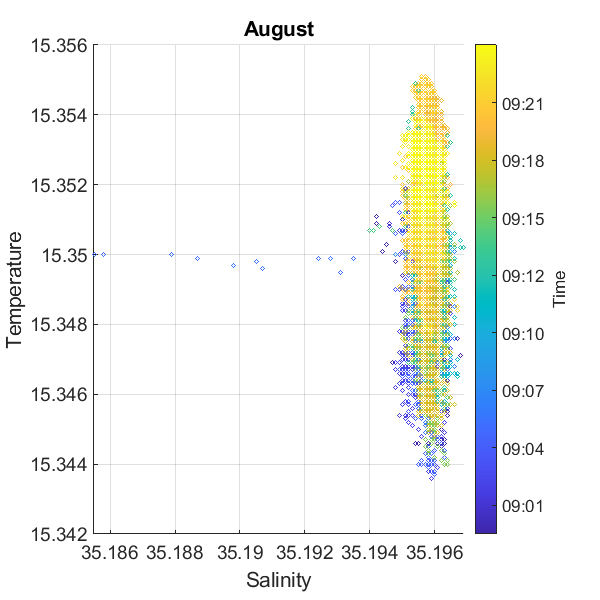

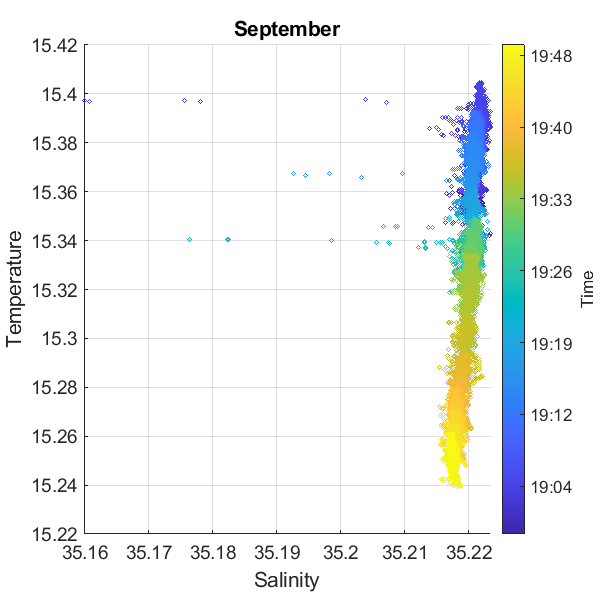

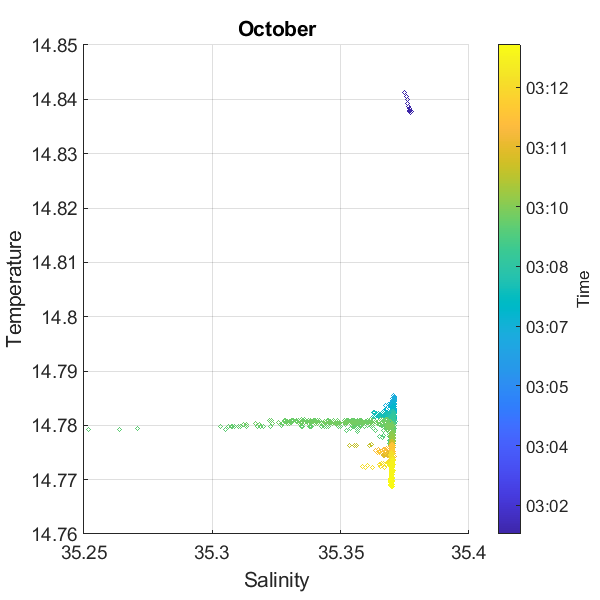

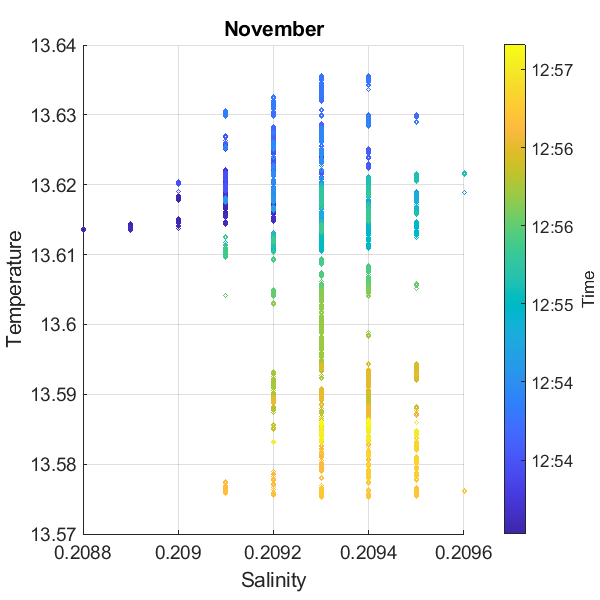

    % replot figure
    figure('Renderer', 'painters', 'Position', [10 20 600 600])
    salt=SCAT_data.Salinity;
    temp=SCAT_data.Temperature;
    time=datetime(SCAT_data.DateString,'InputFormat','yyyy/MM/dd HH:mm:ss.S');
    time=datenum(time);
    scatter(salt,temp,10,time'.')
    set(gca,'FontSize',14);
    c=colorbar;
    cbdate('HH:MM')
    xlabel('Salinity');
    ylabel('Temperature');
    ylabel(c,'Time')
    title(titles(ii))
    grid on
    print(gcf,'-dpng',['figures/FASTCAT_ts_' char(months(ii))]);

    figure;
    t = tiledlayout(3,1);
    nexttile;
    x=time;
    y = salt;
    [Y,dx,ndx] = ddspike(y,[-0.5 0.5],4,5,'n');

loop: 1;  spikes: 8
loop: 2;  spikes: 8
loop: 3;  spikes: 8
loop: 4;  spikes: 8
loop: 5;  spikes: 8


loop: 1;  spikes: 11
loop: 2;  spikes: 11
loop: 3;  spikes: 11
loop: 4;  spikes: 11
loop: 5;  spikes: 11


loop: 1;  spikes: 42
loop: 2;  spikes: 42
loop: 3;  spikes: 42
loop: 4;  spikes: 42
loop: 5;  spikes: 42


loop: 1;  spikes: 37
loop: 2;  spikes: 45
loop: 3;  spikes: 45
loop: 4;  spikes: 45
loop: 5;  spikes: 45


no more spikes found after loop cycle 5


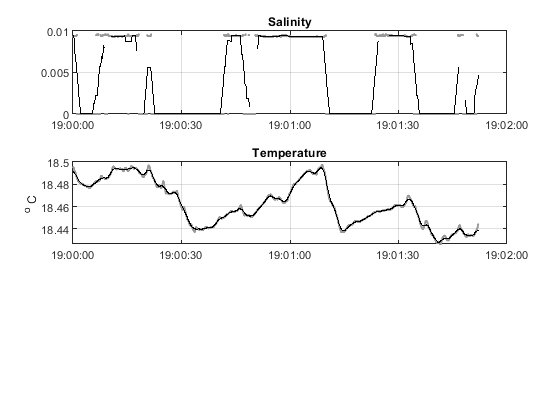

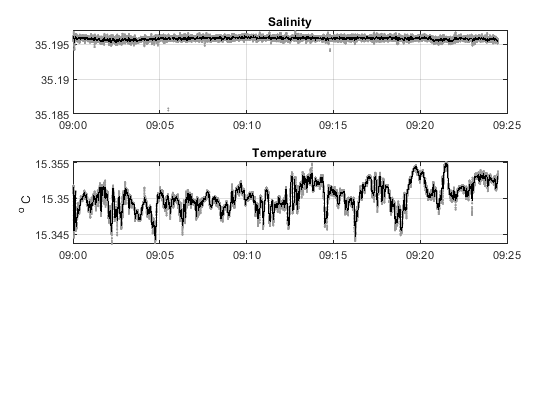

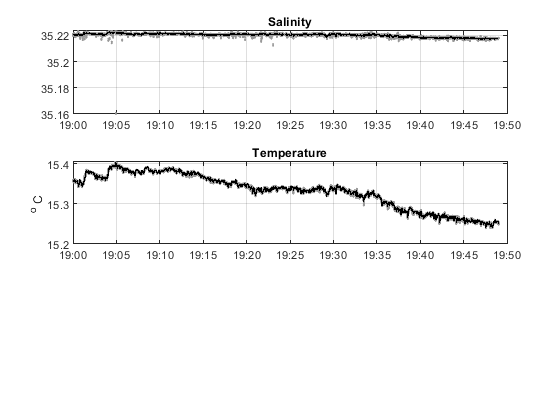

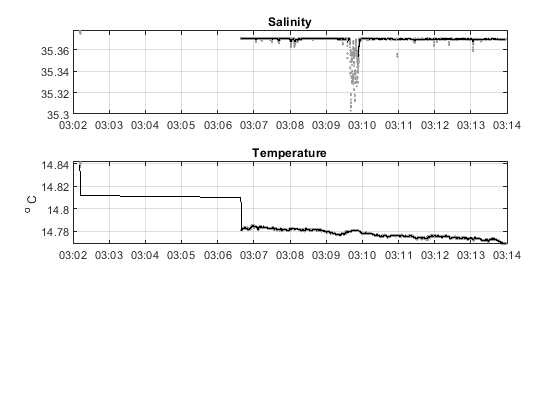

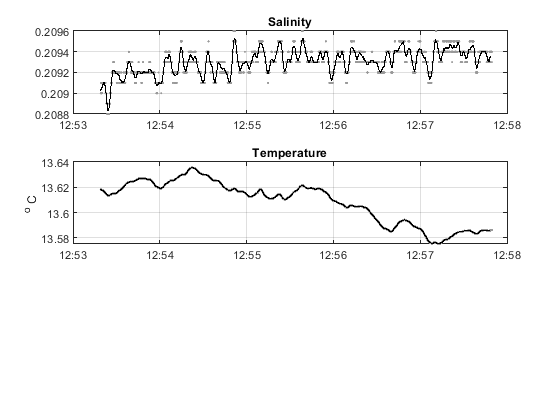

    ix=Y==-9999;
    Y(Y==-9999)=NaN;
    h1=plot(x,Y,'b.','Color',[0.6 0.6 0.6]);
    mmy=movmean(Y,30);
    hold on
    h2=plot(x,mmy,'k-');
    ylabel('')
    grid on
    datetick('x')
    ylabel('');
    title('Salinity');
    
    nexttile;
    y = temp;
    ix=Y==-9999;
    y(Y==-9999)=NaN;
    h1=plot(x,y,'b.','Color',[0.6 0.6 0.6]);
    mmy=movmean(y,30);
    hold on
    h2=plot(x,mmy,'k-');
    ylabel('^o C');
    title('Temperature');
    grid on
    datetick('x')

    
    print(gcf,'-dpng',['figures/sal_example' char(months(ii))]);

## speed of sound

%     figure
%     plot(x,y,'b-');
%     hold on
%     plot([x(1) x(end)],[nanmean(y) nanmean(y)],'r-');
%     ylim([floor(min(y)) ceil(max(y))])
%     title('Speed of sound')
%     ylabel('m/s')
%     
%     print(gcf,'-dpng',['figures/SOS_example' char(months(ii))]);

end